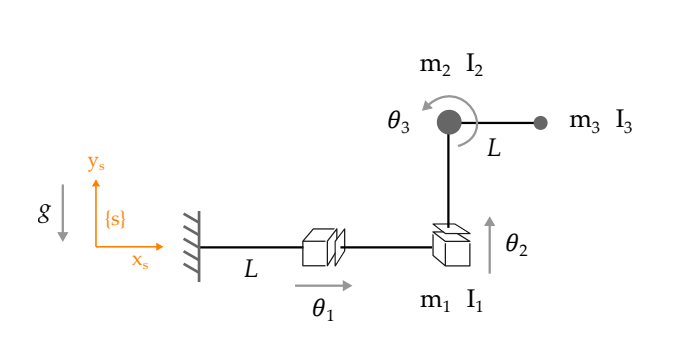

Find the dynamics for the robot shown above. Your answer should be of the form:


$$\tau =M\left(\Theta \right)*\dot{\dot{\theta} } +C\left(\theta ,\dot{\theta} \right)*\dot{\theta} +g\left(\theta \right)$$


List the Mass matrix, the Coriolis matrix, and the Gravity vector. Each center of mass is at the end of the link.

clc;
clear;

syms L g m1 m2 m3 theta1 theta2 theta3 theta1_dot theta2_dot theta3_dot theta1_dot_dot theta2_dot_dot theta3_dot_dot Ix1 Ix2 Ix3 Iy1 Iy2 Iy3 Iz1 Iz2 Iz3 real

theta = [theta1; theta2; theta3];
thetadot = [theta1_dot; theta2_dot; theta3_dot];
thetadotdot = [theta1_dot_dot; theta2_dot_dot; theta3_dot_dot];

% Home matrix till m1 center of mass
M1 = [eye(3),[L;0;0]; 0 0 0 1];
% Home matrix till m2 center of mass
M2 = [eye(3), [L;0;0]; 0 0 0 1];
% Home matrix till m3 center of mass
M3 = [eye(3), [2*L;0;0]; 0 0 0 1];

% Screw for joint 1
S1 = [0;0;0;1;0;0];
% Screw for joint 2
S2 = [0;0;0;0;1;0];
% Screw for joint 3
S3 = [0;0;1;0;0;0];

% Considering m1 center of mass as end-effector
S_eq1 = [S1, zeros(6, 1), zeros(6, 1)];
% Considering m2 center of mass as end-effector
S_eq2 = [S1, S2, zeros(6, 1)];
% Considering m3 center of mass as end-effector
S_eq3 = [S1, S2, S3];

% For center of mass m1
% Forward kinematics
T_1 = fk(M1, S_eq1, theta)

$$T\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & L+\theta_{1}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_1 = T_1(1:3, 1:3);
% Space Jacobian
Js_1 = simplify(expand(JacS(S_eq1, theta)));
% Body Jacobian
Jb_1 = adjointM(inv(T_1))*Js_1;
% Geometric Jacobian
J_geometric_1 = simplify(expand([R_1, zeros(3); zeros(3), R_1] * Jb_1));
% NOTE: For Jw(x1:y1, x2:y2) and Jv(x1:y1, x2:y2), number of columns y1 and
% y2 vary according to the number of joints, thus we change accordingly
Jw1 = J_geometric_1(1:3,1:3)

$$Jw1 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Jv1 = J_geometric_1(4:6, 1:3)

$$Jv1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Inertia_1 = [[Ix1 0 0]
    [0 Iy1 0]
    [0 0 Iz1]];

% For m2 center of mass
T_2 = fk(M2, S_eq2, theta)

$$T\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & L+\theta_{1}\\ 0 & 1 & 0 & \theta_{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_2 = T_2(1:3, 1:3);
Js_2 = simplify(expand(JacS(S_eq2, theta))); % Space Jacobian
Jb_2 = adjointM(inv(T_2))*Js_2; % Body Jacobian
J_geometric_2 = simplify(expand([R_2, zeros(3); zeros(3), R_2] * Jb_2)); % Geometric Jacobian
Jw2 = J_geometric_2(1:3,1:3)

$$Jw2 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Jv2 = J_geometric_2(4:6, 1:3)

$$Jv2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0 \end{array}\right)$$


Inertia_2 = [[Ix2 0 0]
    [0 Iy2 0]
    [0 0 Iz2]];

% For m3 center of mass
T_3 = fk(M3, S_eq3, theta)

$$T\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \theta_{1}+2\,L\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \theta_{2}+2\,L\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_3 = T_3(1:3, 1:3);
Js_3 = simplify(expand(JacS(S_eq3, theta))); % Space Jacobian
Jb_3 = adjointM(inv(T_3))*Js_3; % Body Jacobian
J_geometric_3 = simplify(expand([R_3, zeros(3); zeros(3), R_3] * Jb_3)); % Geometric Jacobian
Jw3 = J_geometric_3(1:3,1:3)

$$Jw3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Jv3 = J_geometric_3(4:6, 1:3)

$$Jv3 = \left(\begin{array}{ccc} 1 & 0 & -2\,L\,\sin\left(\theta_{3}\right)\\ 0 & 1 & 2\,L\,\cos\left(\theta_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$


Inertia_3 = [[Ix3 0 0]
    [0 Iy3 0]
    [0 0 Iz3]];


% Mass Matrix
Mass_Matrix = simplify(expand(m1*(Jv1'*Jv1) + Jw1'*R_1*Inertia_1*R_1'*Jw1 + m2*(Jv2'*Jv2) + Jw2'*R_2*Inertia_2*R_2'*Jw2 + m3*(Jv3'*Jv3) + Jw3'*R_3*Inertia_3*R_3'*Jw3))

$$Mass\_Matrix = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -2\,L\,m_{3}\,\sin\left(\theta_{3}\right)\\ 0 & m_{2}+m_{3} & 2\,L\,m_{3}\,\cos\left(\theta_{3}\right)\\ -2\,L\,m_{3}\,\sin\left(\theta_{3}\right) & 2\,L\,m_{3}\,\cos\left(\theta_{3}\right) & 4\,m_{3}\,L^{2}+{\mathrm{Iz}}_{3} \end{array}\right)$$


% Coriolis Matrix
Coriolis_Matrix = coriolis(Mass_Matrix, theta, thetadot)

$$Coriolis\_Matrix = \left(\begin{array}{ccc} 0 & 0 & -2\,L\,m_{3}\,\theta_{\dot{3}}\,\cos\left(\theta_{3}\right)\\ 0 & 0 & -2\,L\,m_{3}\,\theta_{\dot{3}}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$


% Height of each center of mass
h1 = T_1(2, 4)

$$h1 = 0$$

h2 = T_2(2, 4)

$$h2 = \theta_{2}$$

h3 = T_3(2, 4)

$$h3 = \theta_{2}+2\,L\,\sin\left(\theta_{3}\right)$$


% Potential Energy
P = g*m1*h1 + g*m2*h2 + g*m3*h3

$$P = g\,m_{3}\,\left(\theta_{2}+2\,L\,\sin\left(\theta_{3}\right)\right)+g\,m_{2}\,\theta_{2}$$


% Gravity vector
gravity_vector = simplify(expand([diff(P, theta(1)); diff(P, theta(2)); diff(P, theta(3))]))

$$gravity\_vector = \left(\begin{array}{c} 0\\ g\,\left(m_{2}+m_{3}\right)\\ 2\,L\,g\,m_{3}\,\cos\left(\theta_{3}\right) \end{array}\right)$$


% Tau calculation
tau = simplify(expand(Mass_Matrix*thetadotdot + Coriolis_Matrix*thetadot + gravity_vector))

$$tau = \left(\begin{array}{c} -2\,L\,m_{3}\,\cos\left(\theta_{3}\right)\,{\theta_{\dot{3}}}^{2}+m_{1}\,\theta_{\dot{\dot{1}}}+m_{2}\,\theta_{\dot{\dot{1}}}+m_{3}\,\theta_{\dot{\dot{1}}}-2\,L\,m_{3}\,\theta_{\dot{\dot{3}}}\,\sin\left(\theta_{3}\right)\\ -2\,L\,m_{3}\,\sin\left(\theta_{3}\right)\,{\theta_{\dot{3}}}^{2}+g\,m_{2}+g\,m_{3}+m_{2}\,\theta_{\dot{\dot{2}}}+m_{3}\,\theta_{\dot{\dot{2}}}+2\,L\,m_{3}\,\theta_{\dot{\dot{3}}}\,\cos\left(\theta_{3}\right)\\ {\mathrm{Iz}}_{3}\,\theta_{\dot{\dot{3}}}+4\,L^{2}\,m_{3}\,\theta_{\dot{\dot{3}}}+2\,L\,g\,m_{3}\,\cos\left(\theta_{3}\right)+2\,L\,m_{3}\,\theta_{\dot{\dot{2}}}\,\cos\left(\theta_{3}\right)-2\,L\,m_{3}\,\theta_{\dot{\dot{1}}}\,\sin\left(\theta_{3}\right) \end{array}\right)$$